## Open or consolidate data files

clear
is_Mac = 1;
consolidate = 0;

if is_Mac
    save_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/database/general';
    data_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/database/single';
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw')) %addpath(genpath('.\sw'))
else
    save_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\database\general';
    data_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\database\single';
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
%database_header = ["ID","Item","Windspeed[m/s]","Airspeed[m/s]","Skew[deg]","Skew_sp[deg]","Mot_Status","Excitation","Mx[Nm]","My[Nm]","Mz[Nm]","Fx[N]","Fy[N]","Fz[N]","Mot_F[pwm]","Mot_R[pwm]","Mot_B[pwm]","Mot_L[pwm]","Ail_L[pwm]","Ail_R[pwm]","Elev[pwm]","Rud[pwm]","Pitch[deg]"];    
database_header = ["ID","Item","Windspeed","Airspeed","Skew","Skew_sp","Mot_Status","Excitation","Mx","My","Mz","Fx","Fy","Fz","Mot_F","Mot_R","Mot_B","Mot_L","Ail_L","Ail_R","Elev","Rud","Pitch"];
if consolidate
    xlsxFiles = dir(fullfile(data_path,'*.xlsx')); 
    numfiles = length(xlsxFiles);
    mydata = cell(1, numfiles);
    all    = [];
    for k = 1:numfiles 
      mydata{k} = xlsread(fullfile(data_path,xlsxFiles(k).name)); 
      all = [all;mydata{k}];
    end
    Table = array2table(all,'VariableNames',database_header);
    name = 'static_test_1.xlsx';
    table_path_format = fullfile(save_path,name);
    writetable(Table,table_path_format); 
else
    xlsxFiles = dir(fullfile(save_path,'*.xlsx'));
    all = xlsread(fullfile(save_path,xlsxFiles.name)); 
    Table = array2table(all,'VariableNames',database_header);
end


## Perform transformation from balance to drone c.g. and apply calibration

data = Table;

if is_Mac
    path = '/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/OJF/calibration';
else
    path = 'C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\OJF\calibration';
end
name = strcat('calibration.txt');
fid = fopen(fullfile(path,name));
format = sprintf('%s', repmat('%f', 1, 7));
calibration = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);

for i =1:size(data,1)
    int_cal = interp1(calibration(:,1),calibration(:,2:end),data.Windspeed(i));
    data.Fx(i) = data.Fx(i)-int_cal(1);
    data.Fy(i) = data.Fy(i)-int_cal(2);
    data.Fz(i) = data.Fz(i)-int_cal(3);
    data.Mx(i) = data.Mx(i)-int_cal(4);
    data.My(i) = data.My(i)-int_cal(5);
    data.Mz(i) = data.Mz(i)-int_cal(6);
end

pole = [0,0,-1.04].'; %[0,0,-1]90.5+5.5+8
m_i  = [data.Mx,data.My,data.Mz];
f_i  = [data.Fx,data.Fy,data.Fz];
m_e  = m_i + cross(f_i,pole.'.*ones(size(f_i)));
data.Mx = m_e(:,1);
data.My = m_e(:,1);
data.Mz = m_e(:,1);

## **Question to be answered**

*How can the effectiveness of the ailerons be modelled with skew, airspeed, mot cmd(check if can assume no).*

How can the effectiveness of the tail be modelled with skew(check if can assume no), airspeed, mot cmd(check if can assume no), push cmd(check if can assume no). 

How can lift be modelled with respect to airspeed, skew, pitch and mot cmd(check if can assume no). 

Yawing moment and Roll moment from rotating the wing

**LEFT AILERON - Idle motors - Roll Moment**

The inital model has the form of:


$$b_{\textrm{al}} \,k_{\textrm{al}} \,v^2 \,{\sin \left(\Lambda \right)}^3$$


v = unique(Table.Windspeed);
unit_header = ["ID","Item","Windspeed [m/s]","Airspeed [m/s]","Skew [deg]","Skew_sp [deg]","Mot_Status","Excitation","Mx [Nm]","My [Nm]","Mz [Nm]","Fx [N]","Fy[N]","Fz [N]","Mot_F [pwm]","Mot_R [pwm]","Mot_B [pwm]","Mot_L [pwm]","Ail_L [pwm]","Ail_R [pwm]","Elev [pwm]","Rud [pwm]","Pitch [deg]"];    
leg_v = [];
for i=1:max(size(v))
    leg_v= [leg_v,strcat(string(round(v(i))),'[m/s]'),''];
end
for k=0:3
    figure(k+1)
    clf
    cla
    t = tiledlayout(2,3);
    for j=9:14
        nexttile
        for i=1:max(size(v))
            out  = table_sifter(Table,[-1,k,v(i),-1,-1,90,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            bias = table_sifter(Table,[-1,5,v(i),-1,-1,90,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(19+k),out.(j)-bias.(j),1,i)
        end
        xlabel(unit_header(19+k))
        ylabel(unit_header(j))
        
        grid on
        grid minor

    end
    lgd = legend(leg_v,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,out.Properties.VariableNames(19+k))
end

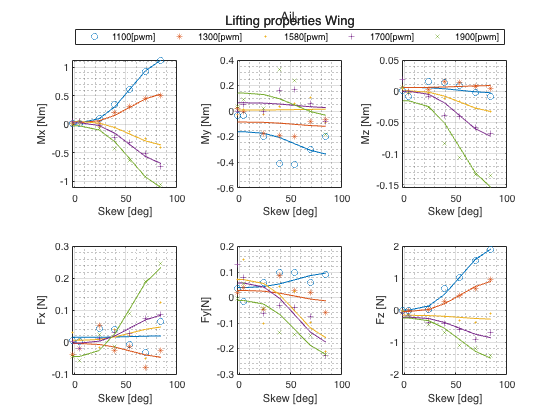

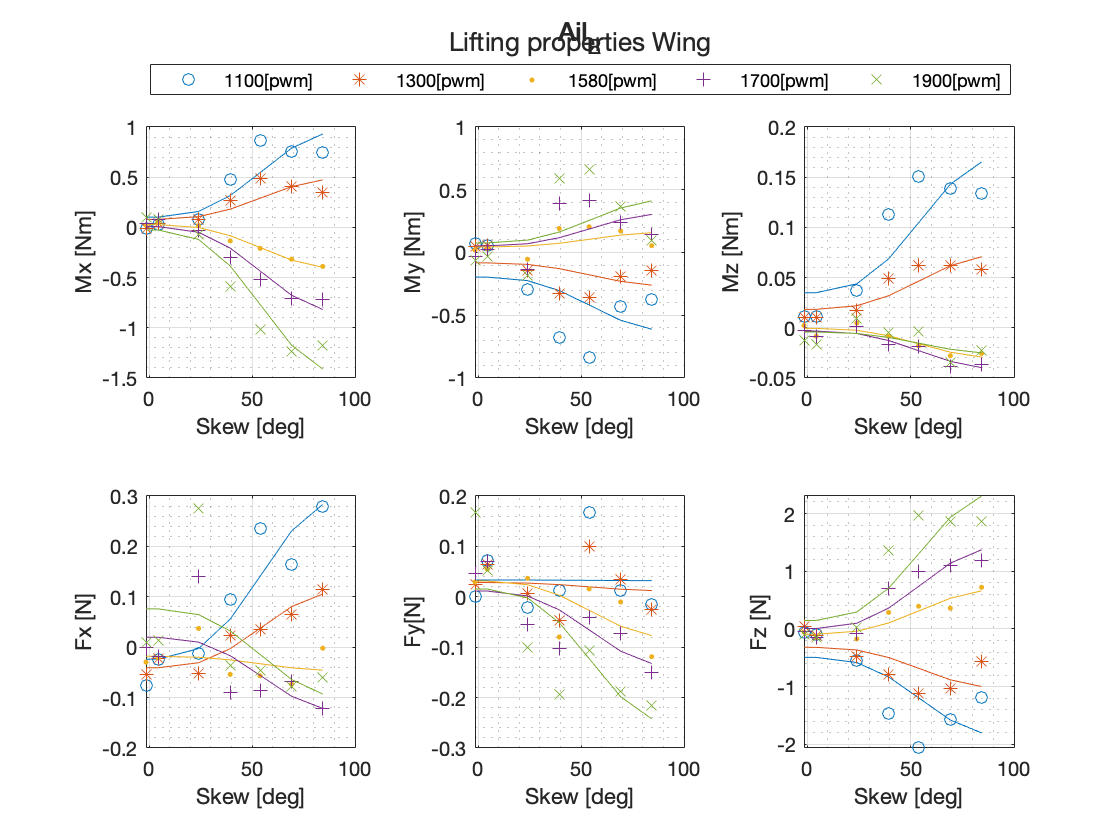

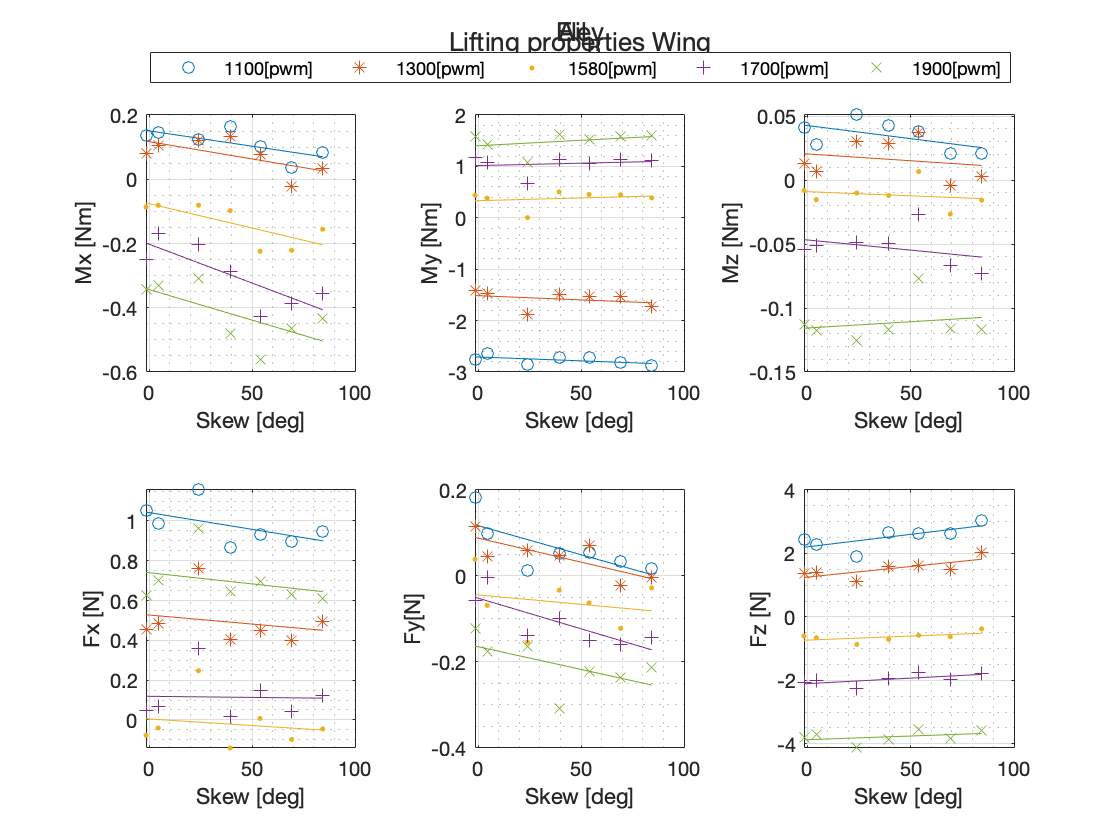

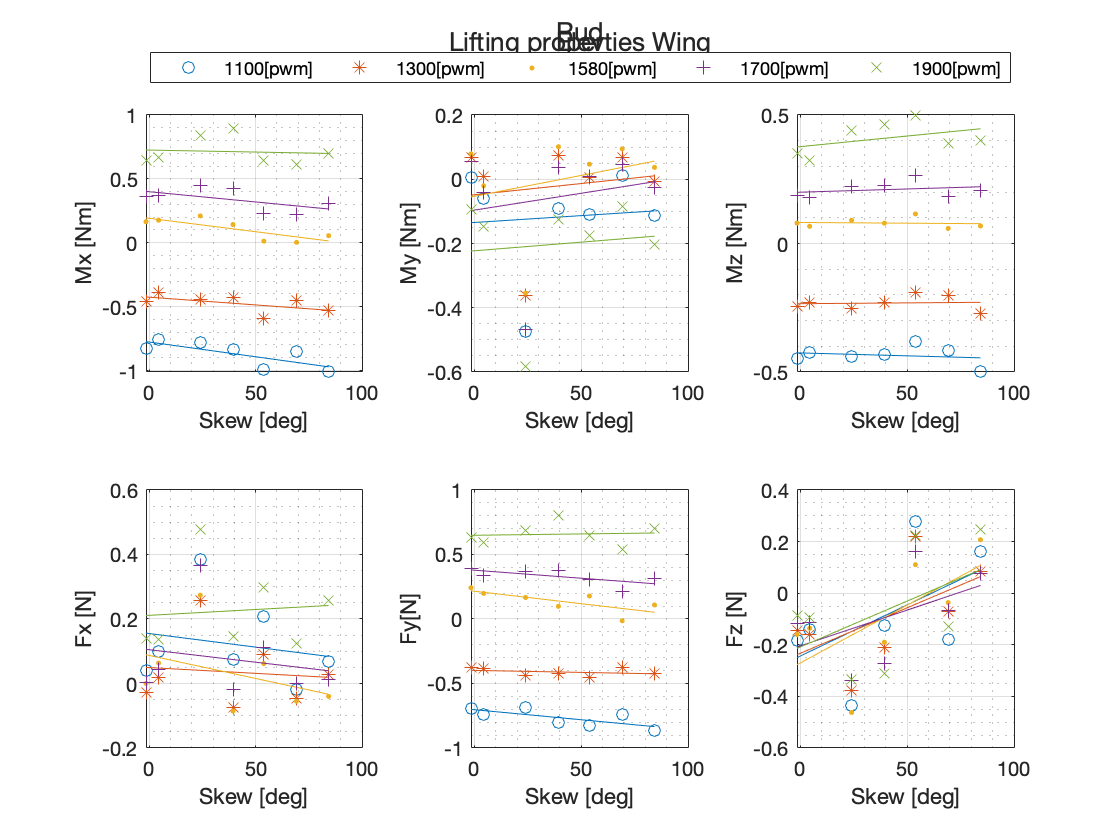

baseline = k;
cmd_idx = unique(Table.Excitation);
cmd = [1100,1300,1580,1700,1900];
leg_cmd = [];
for i=1:max(size(cmd))
    leg_cmd= [leg_cmd,strcat(string(round(cmd(i))),'[pwm]'),''];
end
for k=0:3
    figure(baseline+k+1)
    clf
    cla
    t = tiledlayout(2,3);
    if k < 2
        order = 12;
    else
        order=1;
    end
    for j=9:14
        nexttile
        for i=1:max(size(cmd_idx))
            out  = table_sifter(Table,[-1,k,v(3),-1,-1,-1,0,cmd_idx(i),-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            bias = table_sifter(Table,[-1,5,v(3),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(5),out.(j)-bias.(j),order,i)
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        
        grid on
        grid minor
        hold off

    end
    lgd = legend(leg_cmd,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,out.Properties.VariableNames(19+k))
end

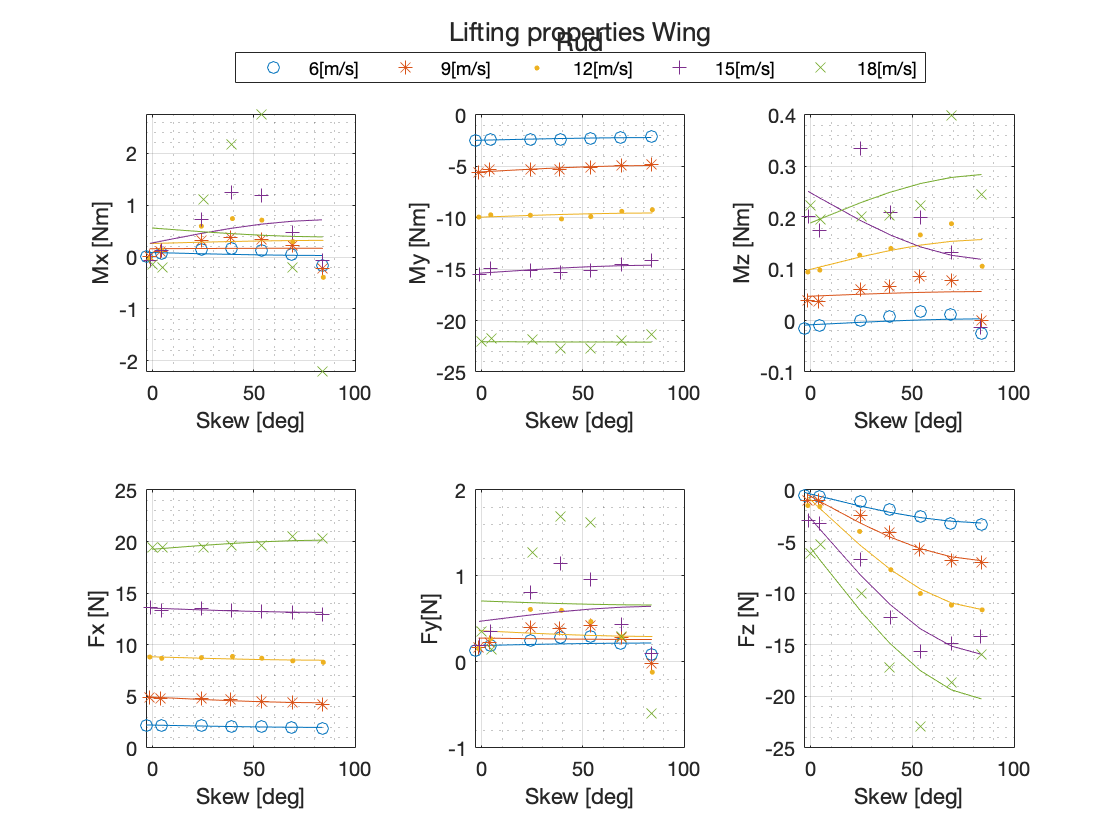

baseline = k;
%for k=0:3
    figure(baseline+k+1)
    clf
    cla
    t = tiledlayout(2,3);
    order=10;
    for j=9:14
        nexttile
        for i=1:max(size(v))
            out  = table_sifter(Table,[-1,5,v(i),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(5),out.(j),order,i)
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        
        grid on
        grid minor
        hold off

    end
    lgd = legend(leg_v,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,'Lifting properties Wing')

%end

% Check linear assumption 90deg max airspeed
Sifter       = (Table.Mot_Status==0).*(Table.Item==0).*(Table.Skew>84).*(Table.Airspeed==max(Table.Airspeed));
Sifter_bias  = (Table.Mot_Status==0).*(Table.Item==5).*(Table.Skew>84).*(Table.Airspeed==max(Table.Airspeed));
Sifter2      = (Table.Mot_Status==1).*(Table.Item==0).*(Table.Skew>84).*(Table.Airspeed==max(Table.Airspeed));
Sifter2_bias = (Table.Mot_Status==1).*(Table.Item==5).*(Table.Skew>84).*(Table.Airspeed==max(Table.Airspeed));
Sifter3      = (Table.Mot_Status==2).*(Table.Item==0).*(Table.Skew>84).*(Table.Airspeed==max(Table.Airspeed));
Sifter3_bias = (Table.Mot_Status==2).*(Table.Item==5).*(Table.Skew>84).*(Table.Airspeed==max(Table.Airspeed));

M_roll = Table.Mx(Sifter==1)-Table.Mx(Sifter_bias==1);
cmd    = Table.Ail_L(Sifter==1) ;
M_roll2 = Table.Mx(Sifter2==1)-Table.Mx(Sifter2_bias==1);
cmd2    = Table.Ail_L(Sifter2==1) ;
M_roll3 = Table.Mx(Sifter3==1)-Table.Mx(Sifter3_bias==1);
cmd3    = Table.Ail_L(Sifter3==1) ;
lin_coef = [cmd,ones(size(cmd))]\M_roll;

figure(2)
clf
plot(cmd,M_roll,'*')
hold on 
plot(cmd,[cmd,ones(size(cmd))]*lin_coef)
plot(cmd2,M_roll2,'.')
plot(cmd3,M_roll3,'+')
grid on
grid minor
xlabel("CMD [pwm]")
ylabel("Roll Moment [Nm]")
legend("Actual","Lin Fit")
figure(4)
clf
hold on
grid on 
grid minor
skew_q = unique(Table.Skew_sp);

for n=0:max(Table.Excitation)
    Sifter = (Table.Mot_Status==0).*(Table.Item==0).*(Table.Airspeed==max(Table.Airspeed)).*(Table.Excitation==n);%.*(Table.Skew_sp==90);
    Sifter_bias = (Table.Mot_Status==0).*(Table.Item==5).*(Table.Airspeed==max(Table.Airspeed));%.*(Table.Skew_sp==90));
    plot(Table.Skew(Sifter==1),Table.Mx(Sifter==1)-Table.Mx(Sifter_bias==1))

end
yline(0,'--','Zero');
legend('1100','1300','1580','1700','1900')

**Right AILERON - Idle motors - Roll Moment**

The inital model has the form of:


$$b_{\textrm{al}} \,k_{\textrm{al}} \,v^2 \,{\sin \left(\Lambda \right)}^3$$


% Check linear assumption 90deg max airspeed
Sifter = (Table.Mot_Status==0).*(Table.Item==1).*(Table.Skew>84).*(Table.Airspeed==max(Table.Airspeed));
M_roll = Table.Mx(Sifter==1);
cmd    = Table.Ail_R(Sifter==1) ;
lin_coef = [cmd,ones(size(cmd))]\M_roll;

figure(3)
clf
plot(cmd,M_roll,'*')
hold on 
plot(cmd,[cmd,ones(size(cmd))]*lin_coef)
xlabel("CMD [pwm]")
ylabel("Roll Moment [Nm]")
legend("Actual","Lin Fit")




Sifter = (Table.Mot_Status==0).*(Table.Item==0);
M_roll = Table.Mx(Sifter==1);
Skew   = Table.Skew(Sifter==1);
V      = Table.Airspeed(Sifter==1);
cmd    = Table.Ail_L(Sifter==1) 

cmd =         1100
        1300
        1580
        1700
        1900
        1100
        1300
        1580
        1700
        1900


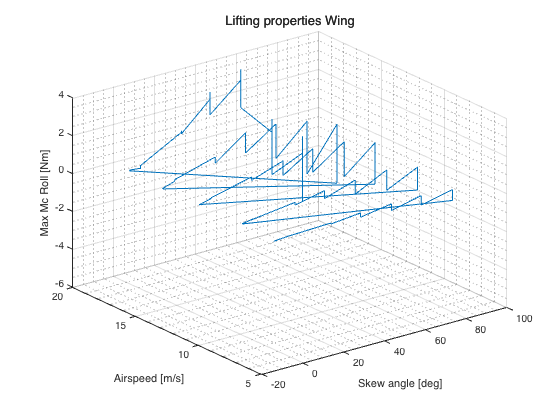


b_al   = 0.65; %[m]
k_al   = M_roll./(b_al.*cmd.*(V.^2).*sin(deg2rad(Skew)).^3);

figure(2)
clf
plot3(Skew,V,M_roll)
hold on 
%tri = delaunay(Skew,V);
%trisurf(tri,Skew,V,M_roll)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc Roll [Nm]')

**Plots**

Print some plots to have an idea of the quality of the results

% Wing behaviour
figure(1)
clf
tiledlayout(2,3);
nexttile

xlabel('Time [s]')
ylabel('Airspeed [m/s]')
nexttile
contourf(rad2deg(L),V,M_c_roll,20)